# TP - Différences finies pour le problème de Poisson

Cas particulier : N = 4

On résout le problème :


$$-\Delta u(x,y)=f(x,y),\qquad (x,y)\in ]0,1[\times]0,1[$$


avec une solution exacte donnée par :


$$u(x,y)=\cos\bigl(\pi(x+y)\bigr)\sin\bigl(\pi(x-y)\bigr)$$


Les conditions aux limites sont imposées avec la solution exacte.

clear;
clc;
close all;

## 1. Choix du nombre de points intérieurs et définition du pas h

N = 16;

h = 1/(N+1);

disp("Nombre de points intérieurs N :")

Nombre de points intérieurs N :


disp(N);

    16




disp("Pas du maillage h :")

Pas du maillage h :


disp(h);

    0.0588



## 2. Définition de la solution exacte et du second membre

% Solution exacte
uexact = @(x,y) cos(pi*(x+y)) .* sin(pi*(x-y));

% Second membre f obtenu à partir de -Delta u = f
f = @(x,y) 2*pi^2 * ( sin(2*pi*x) - sin(2*pi*y) );

## 3. Construction des points intérieurs

% Pour N = 4, on obtient :
% x_int = [0.2 0.4 0.6 0.8]
% y_int = [0.2 0.4 0.6 0.8]

x_int = h:h:1-h;
y_int = h:h:1-h;

disp("Points intérieurs en x :")

Points intérieurs en x :


disp(x_int);

  Columns 1 through 10

    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882

  Columns 11 through 16

    0.6471    0.7059    0.7647    0.8235    0.8824    0.9412




disp("Points intérieurs en y :")

Points intérieurs en y :


disp(y_int);

  Columns 1 through 10

    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882

  Columns 11 through 16

    0.6471    0.7059    0.7647    0.8235    0.8824    0.9412



## 4. Maillage intérieur avec ndgrid

% X_int(i,j) contient la coordonnée x du point intérieur.
% Y_int(i,j) contient la coordonnée y du point intérieur.

[X_int, Y_int] = ndgrid(x_int, y_int);

disp("Matrice X_int :")

Matrice X_int :


disp(X_int);

  Columns 1 through 10

    0.0588    0.0588    0.0588    0.0588    0.0588    0.0588    0.0588    0.0588    0.0588    0.0588
    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176    0.1176
    0.1765    0.1765    0.1765    0.1765    0.1765    0.1765    0.1765    0.1765    0.1765    0.1765
    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353    0.2353
    0.2941    0.2941    0.2941    0.2941    0.2941    0.2941    0.2941    0.2941    0.2941    0.2941
    0.3529    0.3529    0.3529    0.3529    0.3529    0.3529    0.3529    0.3529    0.3529    0.3529
    0.4118    0.4118    0.4118    0.4118    0.4118    0.4118    0.4118    0.4118    0.4118    0.4118
    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706    0.4706
    0.5294    0.5294    0.5294    0.5294    0.5294    0.5294    0.5294    0.5294    0.5294    0.5294
    0.5882    0.5882    0.5882    0.5882    0.5882    0.5882    0.5


disp("Matrice Y_int :")

Matrice Y_int :


disp(Y_int);

  Columns 1 through 10

    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294    0.5882
    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4

## 5. Construction de la matrice A

% Le schéma aux différences finies est :
%
% 4u(i,j) - u(i-1,j) - u(i+1,j) - u(i,j-1) - u(i,j+1)
% =
% h^2 f(x_i,y_j)

e = ones(N,1);

% Matrice tridiagonale T
T = spdiags([-e 4*e -e], [-1 0 1], N, N);

% Matrice identité
I = speye(N);

% Matrice qui relie les blocs entre eux
B = spdiags([-e -e], [-1 1], N, N);

% Matrice globale A
A = kron(speye(N), T) + kron(B, I);

disp("Matrice A :")

Matrice A :


disp(full(A));

  Columns 1 through 17

     4    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
    -1     4    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     4    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     4    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     4    -1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     4    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     4    -1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     4    -1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     4    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0 

## 6. Construction du second membre sous forme matricielle

% On construit d'abord une matrice F de taille N x N.
% Cette matrice contient :
%
% h^2 f(x_i,y_j)
%
% puis on ajoute les contributions des bords.

F = zeros(N,N);

for j = 1:N
    for i = 1:N
        
        x = X_int(i,j);
        y = Y_int(i,j);
        
        % Terme principal
        F(i,j) = h^2 * f(x,y);
        
        % Bord gauche : x = 0
        if i == 1
            F(i,j) = F(i,j) + uexact(0,y);
        end
        
        % Bord droit : x = 1
        if i == N
            F(i,j) = F(i,j) + uexact(1,y);
        end
        
        % Bord inférieur : y = 0
        if j == 1
            F(i,j) = F(i,j) + uexact(x,0);
        end
        
        % Bord supérieur : y = 1
        if j == N
            F(i,j) = F(i,j) + uexact(x,1);
        end
        
    end
end

disp("Matrice F contenant le second membre avant vectorisation :")

Matrice F contenant le second membre avant vectorisation :


disp(F);

  Columns 1 through 10

         0   -0.3582   -0.4840   -0.5412   -0.5219   -0.4288   -0.2745   -0.0798    0.1291    0.3238
    0.3582         0   -0.0151   -0.0220   -0.0197   -0.0085    0.0101    0.0335    0.0586    0.0820
    0.4840    0.0151         0   -0.0069   -0.0046    0.0066    0.0252    0.0486    0.0737    0.0971
    0.5412    0.0220    0.0069         0    0.0023    0.0135    0.0321    0.0555    0.0806    0.1040
    0.5219    0.0197    0.0046   -0.0023         0    0.0112    0.0297    0.0531    0.0782    0.1017
    0.4288    0.0085   -0.0066   -0.0135   -0.0112         0    0.0185    0.0420    0.0671    0.0905
    0.2745   -0.0101   -0.0252   -0.0321   -0.0297   -0.0185         0    0.0234    0.0485    0.0719
    0.0798   -0.0335   -0.0486   -0.0555   -0.0531   -0.0420   -0.0234         0    0.0251    0.0485
   -0.1291   -0.0586   -0.0737   -0.0806   -0.0782   -0.0671   -0.0485   -0.0251         0    0.0234
   -0.3238   -0.0820   -0.0971   -0.1040   -0.1017   -0.0905   -0.0

## 7. Transformation du second membre en vecteur b

% Le vecteur b doit avoir le même ordre que les inconnues du vecteur U.
%
% On choisit l'ordre :
%
% U = [u(1,1), u(2,1), u(3,1), u(4,1),
%      u(1,2), u(2,2), ..., u(4,4)]^T

b = zeros(N*N,1);

k = 1;

for j = 1:N
    for i = 1:N
        
        b(k) = F(i,j);
        k = k + 1;
        
    end
end

disp("Vecteur second membre b :")

Vecteur second membre b :


disp(b);

         0
    0.3582
    0.4840
    0.5412
    0.5219
    0.4288
    0.2745
    0.0798
   -0.1291
   -0.3238
   -0.4782
   -0.5713
   -0.5906
   -0.5334
   -0.4075
   -0.4106
   -0.3582
         0
    0.0151
    0.0220
    0.0197
    0.0085
   -0.0101
   -0.0335
   -0.0586
   -0.0820
   -0.1005
   -0.1117
   -0.1140
   -0.1072
   -0.0920
   -0.4075
   -0.4840
   -0.0151
         0
    0.0069
    0.0046
   -0.0066
   -0.0252
   -0.0486
   -0.0737
   -0.0971
   -0.1156
   -0.1268
   -0.1292
   -0.1223
   -0.1072
   -0.5334
   -0.5412
   -0.0220
   -0.0069
         0
   -0.0023
   -0.0135
   -0.0321
   -0.0555
   -0.0806
   -0.1040
   -0.1225
   -0.1337
   -0.1360
   -0.1292
   -0.1140
   -0.5906
   -0.5219
   -0.0197
   -0.0046
    0.0023
         0
   -0.0112
   -0.0297
   -0.0531
   -0.0782
   -0.1017
   -0.1202
   -0.1314
   -0.1337
   -0.1268
   -0.1117
   -0.5713
   -0.4288
   -0.0085
    0.0066
    0.0135
    0.0112
         0
   -0.0185
   -0.0420
   -0.0671
   -0.0905
   -0.1090

## 8. Résolution du système linéaire

% On résout :
%
% A U = b

U = A\b;

disp("Vecteur solution numérique U :")

Vecteur solution numérique U :


disp(U);

         0
    0.1563
    0.2672
    0.3174
    0.3003
    0.2180
    0.0817
   -0.0903
   -0.2747
   -0.4466
   -0.5828
   -0.6649
   -0.6818
   -0.6311
   -0.5197
   -0.3625
   -0.1563
   -0.0000
    0.1108
    0.1610
    0.1437
    0.0612
   -0.0755
   -0.2479
   -0.4328
   -0.6051
   -0.7416
   -0.8238
   -0.8406
   -0.7896
   -0.6777
   -0.5197
   -0.2672
   -0.1108
   -0.0000
    0.0502
    0.0327
   -0.0500
   -0.1870
   -0.3597
   -0.5448
   -0.7174
   -0.8541
   -0.9364
   -0.9531
   -0.9019
   -0.7896
   -0.6311
   -0.3174
   -0.1610
   -0.0502
   -0.0000
   -0.0175
   -0.1004
   -0.2375
   -0.4104
   -0.5957
   -0.7685
   -0.9053
   -0.9877
   -1.0044
   -0.9531
   -0.8406
   -0.6818
   -0.3003
   -0.1437
   -0.0327
    0.0175
   -0.0000
   -0.0829
   -0.2201
   -0.3932
   -0.5787
   -0.7516
   -0.8885
   -0.9709
   -0.9877
   -0.9364
   -0.8238
   -0.6649
   -0.2180
   -0.0612
    0.0500
    0.1004
    0.0829
   -0.0000
   -0.1373
   -0.3104
   -0.4960
   -0.6690
   -0.8060

## 9. Construction du maillage complet avec les bords

% Pour afficher la solution, il faut ajouter les bords.
%
% Pour N = 4, le maillage complet contient 6 points :
%
% 0, 0.2, 0.4, 0.6, 0.8, 1

x_full = 0:h:1;
y_full = 0:h:1;

[X_full, Y_full] = ndgrid(x_full, y_full);

disp("Maillage complet x_full :")

Maillage complet x_full :


disp(x_full);

  Columns 1 through 10

         0    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294

  Columns 11 through 18

    0.5882    0.6471    0.7059    0.7647    0.8235    0.8824    0.9412    1.0000




disp("Maillage complet y_full :")

Maillage complet y_full :


disp(y_full);

  Columns 1 through 10

         0    0.0588    0.1176    0.1765    0.2353    0.2941    0.3529    0.4118    0.4706    0.5294

  Columns 11 through 18

    0.5882    0.6471    0.7059    0.7647    0.8235    0.8824    0.9412    1.0000



## 10. Calcul de la solution exacte sur tout le domaine

U_exact_full = zeros(N+2, N+2);

for j = 1:N+2
    for i = 1:N+2
        
        x = X_full(i,j);
        y = Y_full(i,j);
        
        U_exact_full(i,j) = uexact(x,y);
        
    end
end

disp("Solution exacte sur le maillage complet :")

Solution exacte sur le maillage complet :


disp(U_exact_full);

  Columns 1 through 10

         0   -0.1806   -0.3368   -0.4476   -0.4979   -0.4809   -0.3990   -0.2632   -0.0919    0.0919
    0.1806         0   -0.1562   -0.2670   -0.3172   -0.3003   -0.2184   -0.0826    0.0887    0.2725
    0.3368    0.1562         0   -0.1107   -0.1610   -0.1441   -0.0622    0.0736    0.2450    0.4287
    0.4476    0.2670    0.1107         0   -0.0503   -0.0333    0.0486    0.1844    0.3557    0.5395
    0.4979    0.3172    0.1610    0.0503         0    0.0170    0.0989    0.2347    0.4060    0.5897
    0.4809    0.3003    0.1441    0.0333   -0.0170         0    0.0819    0.2177    0.3890    0.5728
    0.3990    0.2184    0.0622   -0.0486   -0.0989   -0.0819         0    0.1358    0.3071    0.4909
    0.2632    0.0826   -0.0736   -0.1844   -0.2347   -0.2177   -0.1358         0    0.1713    0.3551
    0.0919   -0.0887   -0.2450   -0.3557   -0.4060   -0.3890   -0.3071   -0.1713         0    0.1837
   -0.0919   -0.2725   -0.4287   -0.5395   -0.5897   -0.5728   -0.4

## 11. Construction de la solution numérique complète

% Le vecteur U contient seulement les valeurs aux points intérieurs.
%
% Pour construire une surface complète :
% - on met d'abord la solution exacte partout ;
% - ensuite on remplace seulement l'intérieur par les valeurs numériques.
%
% Cela permet de respecter les conditions aux limites.

U_num_full = U_exact_full;

k = 1;

for j = 1:N
    for i = 1:N
        
        ligne = i + 1;
        colonne = j + 1;
        
        U_num_full(ligne, colonne) = U(k);
        
        k = k + 1;
        
    end
end

disp("Solution numérique complète :")

Solution numérique complète :


disp(U_num_full);

  Columns 1 through 10

         0   -0.1806   -0.3368   -0.4476   -0.4979   -0.4809   -0.3990   -0.2632   -0.0919    0.0919
    0.1806         0   -0.1563   -0.2672   -0.3174   -0.3003   -0.2180   -0.0817    0.0903    0.2747
    0.3368    0.1563   -0.0000   -0.1108   -0.1610   -0.1437   -0.0612    0.0755    0.2479    0.4328
    0.4476    0.2672    0.1108   -0.0000   -0.0502   -0.0327    0.0500    0.1870    0.3597    0.5448
    0.4979    0.3174    0.1610    0.0502   -0.0000    0.0175    0.1004    0.2375    0.4104    0.5957
    0.4809    0.3003    0.1437    0.0327   -0.0175   -0.0000    0.0829    0.2201    0.3932    0.5787
    0.3990    0.2180    0.0612   -0.0500   -0.1004   -0.0829   -0.0000    0.1373    0.3104    0.4960
    0.2632    0.0817   -0.0755   -0.1870   -0.2375   -0.2201   -0.1373   -0.0000    0.1731    0.3588
    0.0919   -0.0903   -0.2479   -0.3597   -0.4104   -0.3932   -0.3104   -0.1731   -0.0000    0.1857
   -0.0919   -0.2747   -0.4328   -0.5448   -0.5957   -0.5787   -0.4

## 12. Visualisation de la solution analytique

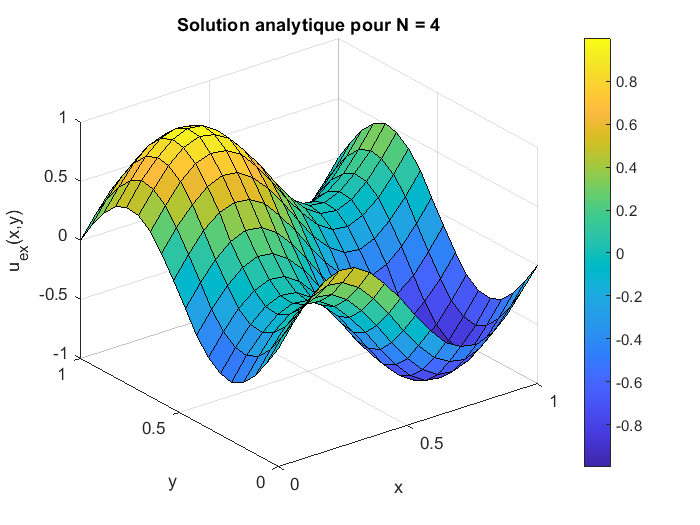

figure;

surf(X_full, Y_full, U_exact_full);

xlabel('x');
ylabel('y');
zlabel('u_{ex}(x,y)');
title(sprintf('Solution numérique pour N = %d', N));

colorbar;
grid on;

## 13. Visualisation de la solution numérique

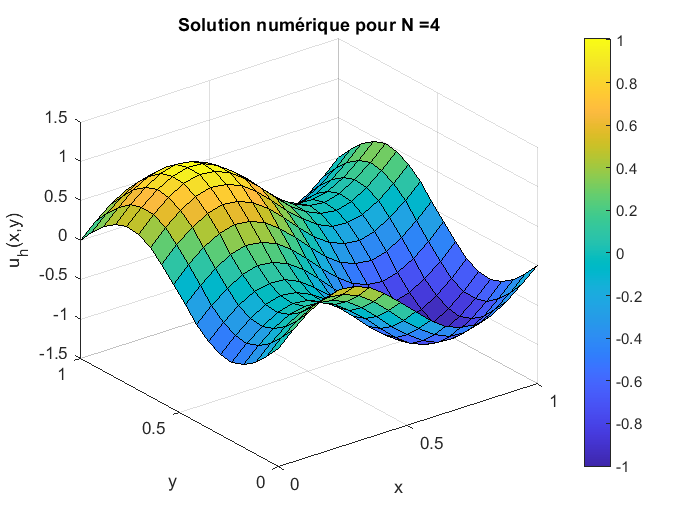

figure;

surf(X_full, Y_full, U_num_full);

xlabel('x');
ylabel('y');
zlabel('u_h(x,y)');
title(sprintf('Solution numérique pour N = %d', N));

colorbar;
grid on;

## 14. Comparaison côte à côte

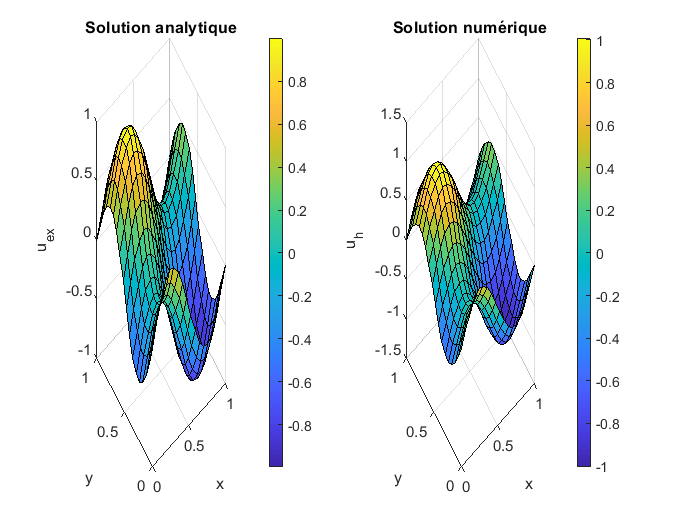

figure;

subplot(1,2,1);

surf(X_full, Y_full, U_exact_full);

xlabel('x');
ylabel('y');
zlabel('u_{ex}');
title(sprintf('Solution numérique pour N = %d', N));
colorbar;
grid on;

subplot(1,2,2);

surf(X_full, Y_full, U_num_full);

xlabel('x');
ylabel('y');
zlabel('u_h');
title(sprintf('Solution numérique pour N = %d', N));
colorbar;
grid on;

## 15. Calcul simple de l'erreur pour vérifier

Erreur = U_exact_full - U_num_full;

Erreur_absolue = abs(Erreur);

disp("Erreur absolue sur le maillage complet :")

Erreur absolue sur le maillage complet :


disp(Erreur_absolue);

  Columns 1 through 10

         0         0         0         0         0         0         0         0         0         0
         0         0    0.0001    0.0002    0.0002    0.0000    0.0004    0.0009    0.0016    0.0022
         0    0.0001    0.0000    0.0001    0.0000    0.0004    0.0010    0.0019    0.0030    0.0041
         0    0.0002    0.0001    0.0000    0.0001    0.0006    0.0014    0.0026    0.0040    0.0054
         0    0.0002    0.0000    0.0001    0.0000    0.0005    0.0015    0.0028    0.0044    0.0060
         0    0.0000    0.0004    0.0006    0.0005    0.0000    0.0010    0.0024    0.0041    0.0059
         0    0.0004    0.0010    0.0014    0.0015    0.0010    0.0000    0.0015    0.0032    0.0051
         0    0.0009    0.0019    0.0026    0.0028    0.0024    0.0015    0.0000    0.0018    0.0037
         0    0.0016    0.0030    0.0040    0.0044    0.0041    0.0032    0.0018    0.0000    0.0019
         0    0.0022    0.0041    0.0054    0.0060    0.0059    0.0


erreur_max = max(Erreur_absolue(:));

disp("Erreur maximale :")

Erreur maximale :


disp(erreur_max);

    0.0091



## 16. Visualisation de l'erreur

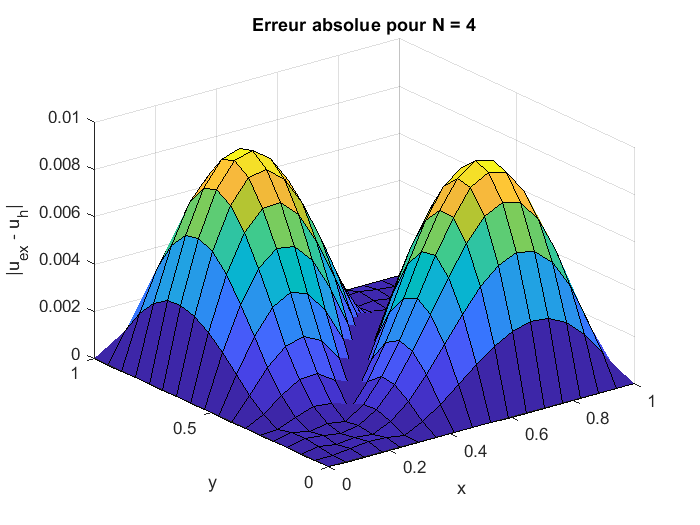

figure;

surf(X_full, Y_full, Erreur_absolue);

xlabel('x');
ylabel('y');
zlabel('|u_{ex} - u_h|');
title(sprintf('Solution numérique pour N = %d', N));

%colorbar;
grid on;